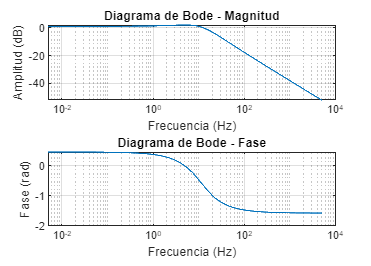

% Ingresar los valores del filtro pasabandas 
f0 = input('Ingrese la frecuencia central del filtro (en Hz): ');
BW = input('Ingrese el ancho de banda del filtro (en Hz): ');
A = input('Ingrese la ganancia del filtro (en dB): ');

% Crear vector de frecuencias
f = logspace(log10(f0) - 3, log10(f0) + 3, 1000);

% Calcular la respuesta en frecuencia del filtro pasabandas
H = 10^(A/20) ./ sqrt(1 + ((f./f0) - 1).^2 / (BW/f0)^2);

% Calcular la fase del filtro pasabandas (opcional)
phi = -atan((f./f0 - 1) / (BW/f0));

% Diagrama de Bode
figure;
subplot(2, 1, 1);
semilogx(f, 20*log10(abs(H)));
grid on;
xlabel('Frecuencia (Hz)');
ylabel('Amplitud (dB)');
title('Diagrama de Bode - Magnitud');

subplot(2, 1, 2);
semilogx(f, phi);
grid on;
xlabel('Frecuencia (Hz)');
ylabel('Fase (rad)');
title('Diagrama de Bode - Fase');